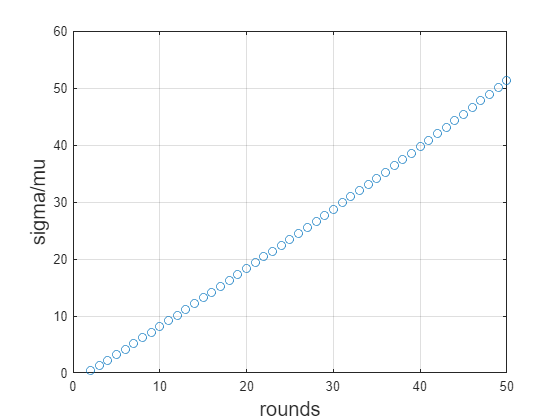

clear 
close all

omega = 0.01;
T =1000;
beta = linspace(1e-4,1e-2,T);
alpha = zeros(1,T);
mu = zeros(1,T);
sigma = zeros(1,T);
alpha(1) = 1-beta(1);
for i=2:T
    alpha(i) = alpha(i-1)*(1-beta(i));
    mu(i) = (beta(i)*sqrt(alpha(i-1))+sqrt(1-beta(i))*(1-alpha(i-1))*sqrt(alpha(i)))/(1-alpha(i))*omega;
    sigma(i) = sqrt(1-beta(i))*(1-alpha(i-1))/sqrt(1-alpha(i));
end


figure
plot(1:50,sigma(1:50)./mu(1:50),'o')
xlabel("rounds",FontSize = 15)
ylabel("sigma/mu",FontSize=15)
grid on



temp = 0;
for t = 2:T
    temp = temp+ ((beta(t)*sqrt(alpha(t-1))+sqrt(1-beta(t))*(1-alpha(t-1))*sqrt(alpha(t))))^2/(1-alpha(t))./...
        (1-beta(t))./(1-alpha(t-1))^2;
end

tauA = @(a) a*omega^2/2*temp;
% (order,tau) Curve for the RDP
order = [1.1:0.1:10,11:20]

order =     1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000    5.0000    5.1000    5.2000    5.3000    5.4000    5.5000    5.6000    5.7000    5.8000    5.9000    6.0000


tau = tauA(order)

tau =     2.8178    3.0740    3.3301    3.5863    3.8425    4.0986    4.3548    4.6109    4.8671    5.1233    5.3794    5.6356    5.8918    6.1479    6.4041    6.6602    6.9164    7.1726    7.4287    7.6849    7.9411    8.1972    8.4534    8.7096    8.9657    9.2219    9.4780    9.7342    9.9904   10.2465   10.5027   10.7589   11.0150   11.2712   11.5274   11.7835   12.0397   12.2958   12.5520   12.8082   13.0643   13.3205   13.5767   13.8328   14.0890   14.3452   14.6013   14.8575   15.1136   15.3698



zeta = 1./order.*(1-1./order).^(order-1)

zeta =     0.7153    0.5824    0.4955    0.4328    0.3849    0.3470    0.3161    0.2904    0.2686    0.2500    0.2338    0.2196    0.2071    0.1959    0.1859    0.1769    0.1687    0.1612    0.1544    0.1481    0.1424    0.1370    0.1321    0.1275    0.1232    0.1192    0.1154    0.1119    0.1086    0.1055    0.1025    0.0997    0.0971    0.0946    0.0922    0.0900    0.0878    0.0857    0.0838    0.0819    0.0801    0.0784    0.0768    0.0752    0.0737    0.0722    0.0709    0.0695    0.0682    0.0670


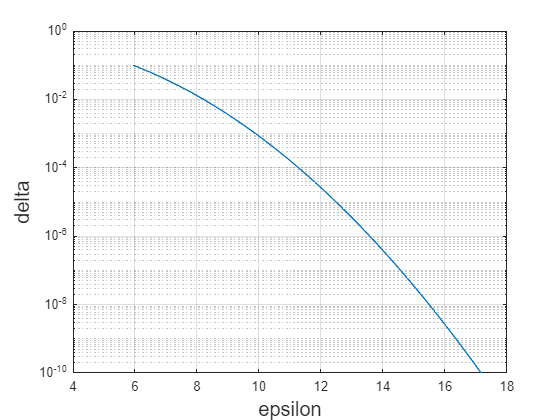

delta = 10.^(-10:0.2:-1);
eps = zeros(size(delta));
for i=1:length(delta)
    if order*delta(i)>=1
        eps(i) = min(max(tau+log(1-delta(i)),0));
    end
    if order*delta(i)>0
        eps(i) = min(1./(order-1).*min(max(0,(order-1).*tau-log(delta(i)./zeta)),log((exp(tau.*(order-1))-1)./order./delta(i)+1)));
    else
        eps(i) = 0;
        disp("Error!")
    end
end
semilogy(eps,delta)
xlabel("epsilon",FontSize=15)
ylabel("delta",FontSize=15)
grid on